# 10 The Dot Product and Convolution

## 10.1 Dot Product

There are several interpretations of the dot product:

- Signal-processing interpretation: a sum of elements in one vector weighted by elements of another vector

- Statistical interpretation: a covariance or similarity between two vectors

- Geometric interpretation: a mapping between vectors (the product of the magnitudes of the two vectors scaled by the cosine of the angle between them)

The algorithm is always the same, and the result is always the same: a single number that is computed based on two vectors of equal length:

### 
$${\textrm{dotproduct}}_{\textrm{ab}} =\sum_{i=1}^n a_i \;b_i$$


*a* and *b* are vectors and *n* is the number of elements in *a* (or *b*).

a = randn(10,1);
b = randn(10,1);

pointwise_result = zeros(size(a));
for i=1:length(a)
    pointwise_result(i) = a(i) * b(i);
end
dotproduct = sum(pointwise_result);
 
dotproduct = sum(a.*b);

dotproduct = a'*b;

% This requires the first vector to be a row vector and the 
% second vector to be a column vector

The geometric interpretation of a dot product is easiest to illustrate visually using two two-element vectors. First, consider that the vectors [a1 b1] and [a2 b2] can be expressed as lines from the origin of the plot to the points described by [a1 b1] and [a2 b2]. Now imagine drawing a line from the end of one vector to the other vector such that they intersect with a 90 ° angle. The length of the projection onto the vector is the dot product. 

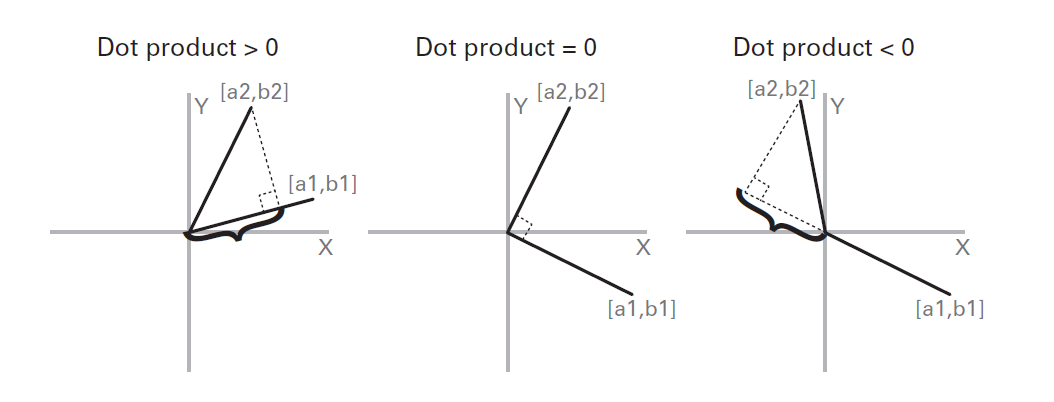

**Figure 10.1**

*Graphical illustration of the geometric interpretation of the dot product between two two-element vectors. Curly brackets illustrate the magnitude of the projection of one vector onto the other (this is the dot product). *

An N -element vector can be conceptualized as a single point in an N -dimensional space, and the dot product between two N -element vectors is the mapping between two hyperlines from the origin of the N -dimensional space to the points defined by the elements (or coordinates) of those vectors. Thus, you can conceptualize an EEG signal that is 640 time points long as a single point in a 640-dimensional space, and the location of that point is defined by the values (coordinates) of the EEG signal at each time point.

## 10.2 Convolution

Convolution in the time domain is an extension of the dot product, it is performed by computing the dot product between two vectors, shifting one vector in time relative to the other vector, computing the dot product again, and so on. 

Convolution can have several interpretations: 

- Signal-processing interpretation: a time series of one signal weighted by another signal that slides along the first signal

- Statistical interpretation: a cross-covariance or the similarity between two vectors over time

- Geometric interpretation: a time series of mappings between two vectors

- Frequency filter

In convolution, one vector is considered the signal, and the other vector is considered the kernel. In practice it is possible to get the same result no matter which vector is labeled signal and which is labeled kernel.

## 10.3 How Does Convolution Work?

Conceptually, convolution entails sliding the kernel along the data and obtaining a result that shows what features the signal and the kernel have in common. This “ commonality ” at each time point is computed as the mapping between the kernel and the signal, that is, the dot product. 

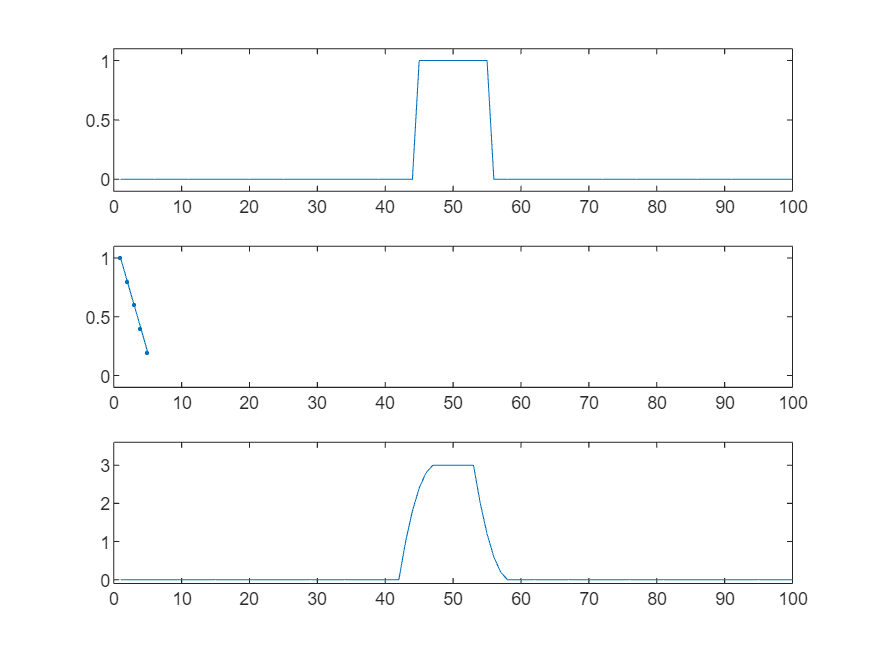

impfun = zeros(1,100);
impfun(45:55)=1;
kernel = [1 .8 .6 .4 .2]; 

matlab_conv_result = conv(impfun,kernel,'same');

figure
subplot(311)
plot(impfun)
set(gca,'ylim',[-.1 1.1])

subplot(312)
plot(kernel,'.-')
set(gca,'xlim',[0 100],'ylim',[-.1 1.1])

subplot(313)
plot(matlab_conv_result)
set(gca,'xlim',[0 100],'ylim',[-.1 3.6])

**Figure 10.2**

*Example of convolution between two vectors, one labeled the signal (panel A) and one labeled the kernel (panel B). Panel C shows the result of the convolution between these two vectors.*

Let illustrates how convolution works, step by step:

- First, flip the kernel backward and line it up with the data as

- Then, compute the dot product by multiplying each point in the kernel by each corresponding point in the data and summing over all of the multiplications

- The dot product between the kernel and the corresponding part of the signal is then placed in a new vector in the position corresponding to the center of the kernel

- Now the kernel is shifted to the right by one time step, but the signal does not move

- This process of computing the dot product and then moving the kernel one step to the right continues until the kernel has reached the end of the data

- The resulting vector is a time series of dot products between the kernel and temporally corresponding equal-length windows of the signal

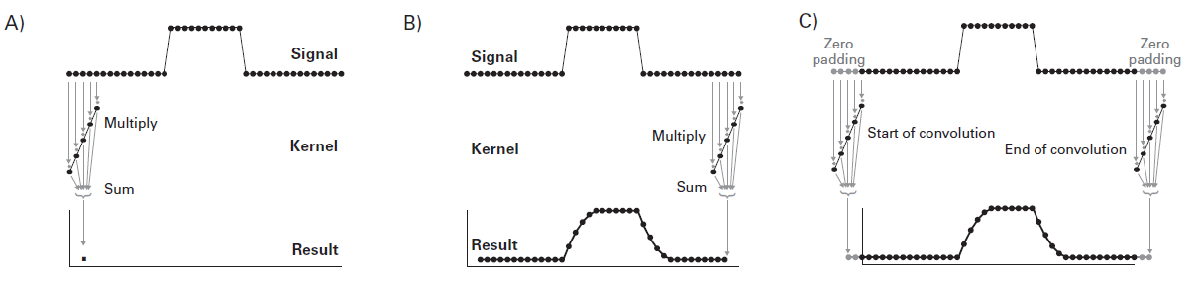

**Figure 10.3**

*Overview of convolution.*

If you line up the kernel and the data such that they have their leftmost points overlapping and continue computing dot products until the kernel and the signal have their rightmost points overlapping, the result of the convolution contains fewer points than the signal. Therefore, convolution actually begins with the kernel aligned to the left such that the rightmost point of the kernel (after it is reversed) overlaps with the leftmost point of the data. Because the two vectors must have the same number of points in order to compute a dot product, zeros are added before the start of the signal. The number of zeros added is the length of the kernel minus one. These extra zeros do not contribute to the result because zero times a kernel is zero. Then, convolution runs each step toward the right, and it stops when the leftmost point of the kernel is aligned with the rightmost point of the signal. Again, zeros are added after the end of the signal to be able to perform a dot product. This means that the result of the convolution between the kernel and the signal is longer than the signal. The formula for how long the result of the convolution will be is length(signal) + length(kernel) – 1. Thus, after you run convolution, you need to trim the result by removing one-half of the length of the kernel from the beginning and one-half of the length of the kernel plus one from the end. This leaves you with a result of convolution equal to the length of the signal.

When written in equations, convolution is often denoted using the asterisk (*), as in: the convolution between *a* and *b* is *a*b* . This can get confusing because in many programming languages, including Matlab, the asterisk indicates multiplication.

To compare the result of convolution with the original signal, it is useful to scale the result of the convolution by the sum of the kernel points. Keep in mind that postconvolution scaling is not the same thing as mean-centering the kernel before convolution.

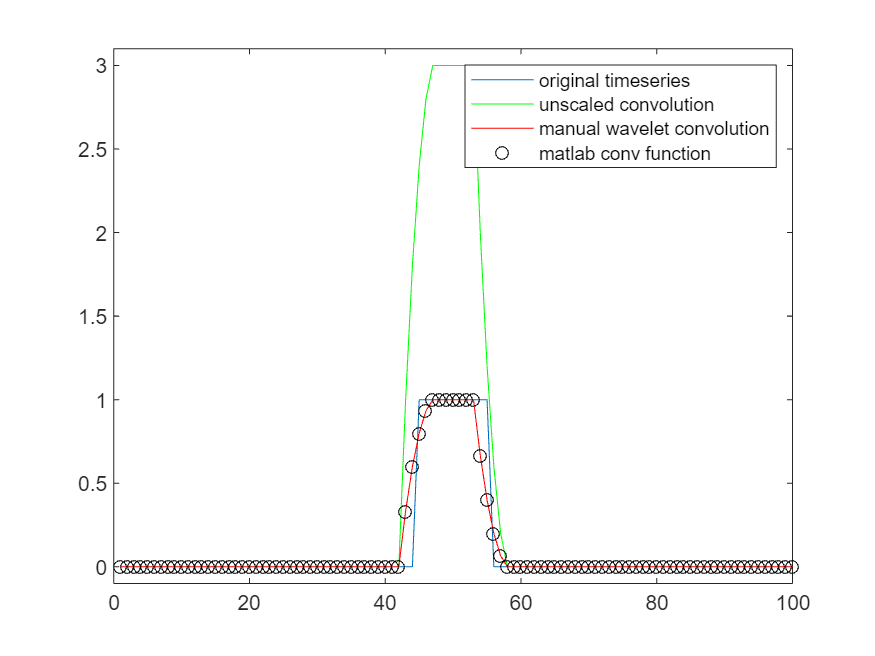

dat4conv = [zeros(1,length(kernel)-1) impfun zeros(1,length(kernel)-1) ];

half_of_kernel_size = ceil((length(kernel)-1)/2);

convolution_result = zeros(1,length(impfun)+length(kernel)-1);

for ti=1:length(convolution_result)-half_of_kernel_size
    convolution_result(ti) = sum(dat4conv(ti:ti+length(kernel)-1).*kernel(end:-1:1));
end

convolution_result = convolution_result(half_of_kernel_size+1:end-half_of_kernel_size);

figure
plot(impfun)
hold on
plot(convolution_result,'g')
plot(convolution_result./sum(kernel),'r')
plot(matlab_conv_result./sum(kernel),'ko')
set(gca,'xlim',[0 100],'ylim',[-.1 3.1])
legend({'original timeseries';'unscaled convolution';'manual wavelet convolution';'matlab conv function'})

**Figure 10.4**

*Overlap of results of manual time-domain convolution and the Matlab frequency-domain convolution function *`conv`* . Also shown is the result of convolution after normalization.*

For completeness, this equation shows the mathematical formula for convolution.

### 
$${\left(a*b\right)}_k =\sum_{i=1}^n a_i {\;b}_{k-i}$$


In this equation, *a* and *b* are the two vectors for which the dot product is computed, *k* indicates that this equation refers to the convolution at time point *k*, and *i* corresponds to the elements in the equal-length parts of vectors *a* and *b*. Vector *b* is the kernel because it is flipped backward (this is the effect of *k – i* ).

## 10.4 Convolution versus Cross-Covariance

Convolution and cross-covariance (or cross-correlation; the cross-correlation is simply the cross-covariance scaled by the variances) are similar in concept but slightly different in algorithm. Both are methods to compute the time-varying mapping between vectors, but with convolution the kernel is reversed, whereas with cross-covariance the kernel is kept in its original orientation. If the convolution kernel is temporally symmetric convolution and cross-covariance yield identical results.

## 10.5 The Purpose of Convolution for EEG Data Analyses

In EEG data analyses, convolution is used to isolate frequency-band-specific activity and to localize that frequency-band-specific activity in time. This is done by convolving wavelets — time-limited sine waves — with EEG data. As the wavelet (the convolution kernel) is dragged along the EEG data (the convolution signal), it reveals when and to what extent the EEG data contain features that look like the wavelet. When convolution is repeated on the same EEG data using wavelets of different frequencies, a time-frequency representation can be formed.